[target, ref] = recorded_samples();

cutoff = 400;
fs = 48000;

target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);


step_sizes = [.001, .005, .01, .05, .1, .5, .9];
block_lens = [128, 256, 512, 1024];
ir_len = 128;

N = length(ir_lens);
S = length(step_sizes);
n_iter = 20;
mses = zeros(N, S, n_iter);
preds = zeros(N, S, length(target));

min_mse = 100;
min_i = 0;
min_j = 0;

filter_order = ir_len * 2;

source_to_ref_cm = 2;
panel_ir = clipped_irs(ir_len, source_to_ref_cm);
panel_ir = highpass(panel_ir, cutoff, fs);

for i = 1:N
    block_len = block_lens(i);

    for j = 1:length(step_sizes)
    
        step_size = step_sizes(j);
    
        fd_fxlms = FD_FxLMS(ref, target, panel_ir, filter_order, step_size, block_len);
        fd_fxlms.gpu = false;
        [pred_i, mses_i] = fd_fxlms.learn(n_iter);
    
        mses(i, j, :) = mses_i;
        preds(i, j, :) = pred_i;
        
        disp(mses_i)

        if mses_i(end) < min_mse
            min_mse = mses_i(end);
            min_i = i;
            min_j = j;
        end
    end

    disp('');

end

   1.0e-06 *

    0.4783    0.4668    0.4556    0.4447    0.4342    0.4239    0.4139    0.4042    0.3948    0.3857    0.3768    0.3682    0.3598    0.3517    0.3438    0.3361    0.3286    0.3213    0.3143    0.3074

   1.0e-06 *

    0.4566    0.4052    0.3607    0.3222    0.2888    0.2598    0.2346    0.2126    0.1935    0.1769    0.1623    0.1495    0.1383    0.1285    0.1198    0.1122    0.1054    0.0994    0.0941    0.0893

   1.0e-06 *

    0.4317    0.3422    0.2750    0.2242    0.1857    0.1564    0.1338    0.1164    0.1027    0.0919    0.0833    0.0763    0.0707    0.0659    0.0620    0.0586    0.0557    0.0531    0.0509    0.0489

   1.0e-06 *

    0.2973    0.1230    0.0727    0.0538    0.0443    0.0384    0.0342    0.0309    0.0282    0.0260    0.0241    0.0226    0.0212    0.0201    0.0192    0.0184    0.0178    0.0174    0.0170    0.0168

   1.0e-06 *

    0.2152    0.0642    0.0415    0.0326    0.0272    0.0234    0.0207    0.0188    0.0176    0.0169    0.0166    0.0165  

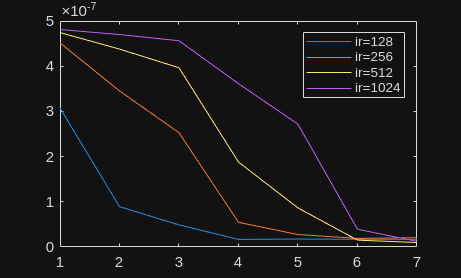

figure
plot(mses(1, :, end))
hold on
plot(mses(2, :, end))
hold on
plot(mses(3, :, end))
hold on
plot(mses(4, :, end))
legend("ir=128", "ir=256", "ir=512", "ir=1024")

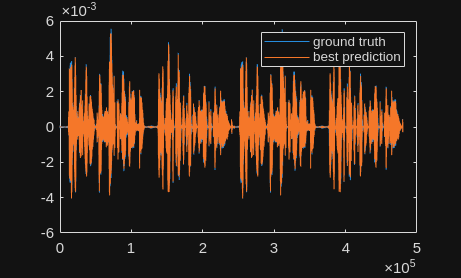

figure
plot(target)
hold on
plot(squeeze(preds(min_i, min_j, :)));
legend("ground truth", "best prediction")
hold off

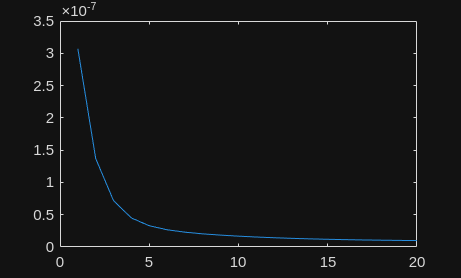

figure
plot(squeeze(mses(min_i, min_j, :)))

min_i % block_length

min_i = 3

min_j % step size

min_j = 7